% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.
% CHECK_GPU_vs_CPU_dynamical_systems_small.mlx
% Rigorous small-example GPU-vs-CPU trajectory and bias-update checks.
% The problem is intentionally tiny so CPU reference calculations are practical.
clear; clc;
repo_root = project_root();
add_project_paths(repo_root);
%% ---------------- Check Hyperparameters ----------------
% check_seeds runs independent deterministic networks.
% check_tolerance sets the reported CPU/GPU discrepancy threshold for trajectory and bias comparisons.
% N_hidden and N_rec are small here to keep CPU checks fast.
% T_sim is the contiguous snippet length used by the check.
% long_trajectory_time is the deterministic source trajectory length from which snippets are sampled.
% long_trajectory_time must be longer than T_sim after burn_in_time is removed.
% epochs is the number of bias-training epochs run before the post-training comparison.
check_seeds = [11 42 99];
training_epochs = 10; % Edit this to choose how many CPU/GPU training epochs the check runs.
long_trajectory_time = single(10.0); % Edit this to choose the long deterministic source trajectory length [s].
opts_template = struct();
opts_template.check_tolerance = struct('abs', 5e-4, 'rel', 5e-4);
opts_template.epochs = training_epochs;
opts_template.system_name = 'vanderpol';
opts_template.N_hidden = 64;
opts_template.N_rec = 10;
opts_template.T_sim = single(1);
opts_template.long_sim_time = long_trajectory_time;
opts_template.burn_in_time = single(0);
opts_template.dt = single(1e-3);
opts_template.dyn_sys_rate = 8;
%% ---------------- Teacher-Forced / Free-Run Schedule ----------------
% use_multistep alternates between true input and generated output.
% W_warmup is teacher-forced steps per cycle; H_free is predicted steps per cycle.
opts_template.use_multistep = true;
opts_template.W_warmup = round(0.1 / opts_template.dt);
opts_template.H_free = round(0 / opts_template.dt);
%% ---------------- Network, Neuron, and Optimiser Parameters ----------------
% These mirror the train scripts but are kept small enough for CPU verification.
opts_template.SCALE = struct('enc', single(2), 'rec', single(0.05), 'dec', single(0.1));
opts_template.NET = struct('p_rec', 1, 'variance_correction', true, ...
    'dale', struct('enable', true, 'p_exc', 0.5, 'sign', []));
opts_template.neuron = struct('tau_u', single(50e-3), 'tau_w', single(500e-3), ...
    'tau_s_rise', single(2e-3), 'tau_s_decay', single(50e-3), ...
    'E_L', single(-70), 'V_th', single(-50), 'V_reset', single(-65), ...
    'a_param', single(0), 'b_param', single(0.5), ...
    'phi_u', single(1), 'delta_u', single(0.8));
opts_template.SCHED = struct('type', 'exponential', 'lr_start', single(5e-2), 'lr_end', single(5e-3));
opts_template.adam = struct('b1', single(0.9), 'b2', single(0.999), 'eps', single(1e-8));
%% ---------------- Run Multiple Independent Checks ----------------
% Each check compares initial trajectories, trajectories after opts_template.epochs bias-training epochs, and trained biases.
check_results = cell(numel(check_seeds), 1);
for ii = 1:numel(check_seeds)
    opts = opts_template;
    opts.seed = check_seeds(ii);
    check_results{ii} = snn_primary_api('check_dynamics', 'dynamical_systems', 'cpu', opts);
    check_results{ii}.seed = check_seeds(ii);
end

%% ---------------- Easy Interpretation ----------------
% Start here. verdict says whether each seed is OK, needs scale/context checking, or needs review.
% main_cpu_gpu_abs is the post-training trajectory mismatch. bias_abs is the trained-bias mismatch.
% loss columns compare CPU and GPU trajectory performance after training.
% *_diff_vs_training_percent columns compare mismatch size with the amount changed by training.
% Training-effect columns are not errors; they should usually be nonzero because the model learned.
summary = snn_check_summary_table(check_results);
qualitative_columns = {'seed','verdict','output_quality','performance_quality','learning_quality','neural_quality','read_first'};
quantitative_columns = {'seed', ...
    'initial_abs','initial_rms','initial_rel', ...
    'after_abs','after_rms','after_rel', ...
    'bias_before_abs','bias_before_rms','bias_before_rel', ...
    'bias_abs','bias_rms','bias_rel', ...
    'cpu_output_change_abs','gpu_output_change_abs','output_training_effect_abs_diff', ...
    'cpu_bias_change_abs','gpu_bias_change_abs','bias_training_effect_abs_diff', ...
    'loss_after_abs','loss_after_diff_percent','loss_delta_abs_diff', ...
    'main_diff_vs_training_percent','bias_diff_vs_training_percent','worst_neural_abs'};
disp('Qualitative summary:');

Qualitative summary:


disp(summary(:, qualitative_columns));

    seed       verdict       output_quality    performance_quality    learning_quality    neural_quality                               read_first                            
    ____    _____________    ______________    ___________________    ________________    ______________    _________________________________________________________________

     11     "CHECK SCALE"    "CHECK SCALE"           "OK"                 "SMALL"              "OK"         "CPU/GPU mismatch is more than 1 percent of the training effect."
     42     "CHECK SCALE"    "CHECK SCALE"           "OK"                 "SMALL"              "OK"         "CPU/GPU mismatch is more than 1 percent of the training effect."
     99     "CHECK SCALE"    "CHECK SCALE"           "SMALL"     

disp('Quantitative output and performance comparisons:');

Quantitative output and performance comparisons:


disp(summary(:, quantitative_columns));

    seed    initial_abs    initial_rms    initial_rel    after_abs    after_rms    after_rel    bias_before_abs    bias_before_rms    bias_before_rel     bias_abs      bias_rms      bias_rel     cpu_output_change_abs    gpu_output_change_abs    output_training_effect_abs_diff    cpu_bias_change_abs    gpu_bias_change_abs    bias_training_effect_abs_diff    loss_after_abs    loss_after_diff_percent    loss_delta_abs_diff    main_diff_vs_training_percent    bias_diff_vs_training_percent    worst_neural_abs
    ____    ___________    

snn_print_check_interpretation(summary, 'Dynamical systems GPU/CPU check');


Dynamical systems GPU/CPU check interpretation
------------------------------------------------------------
What matters: CPU-GPU difference columns should be tiny. Training-effect columns show learning happened; they are not errors.
Overall: CHECK SCALE. 3/3 seed(s) are within tolerance but large relative to the training effect.
Before-training output/trajectory CPU-GPU diff: 0.120285 at seed 99 (relative 0.120285).
After-training output/trajectory CPU-GPU diff: 0.18785 at seed 99 (relative 0.18785).
Before-training bias CPU-GPU diff: 0 at seed 11 (relative 0).
After-training bias CPU-GPU diff: 0.00611305 at seed 42 (relative 0.000303526).
CPU output/trajectory training change: 1.06996 at seed 11.
GPU output/trajectory training change: 1.06624 at seed 11.
CPU bias training change: 0.205843 at seed 42.
GPU bias training change: 0.205822 at seed 42.
CPU-vs-GPU output training-change diff: 0.00543368 at seed 99.
CPU-vs-GPU bias training-change diff: 2.09808e-05 at seed 42.
Post-training

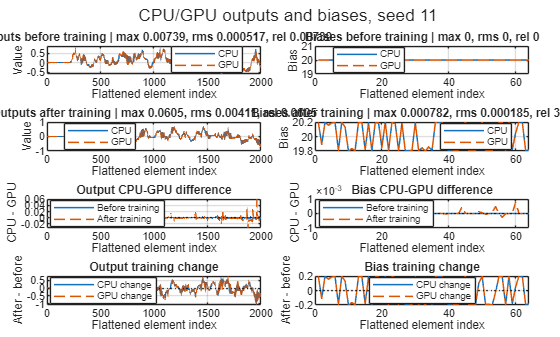

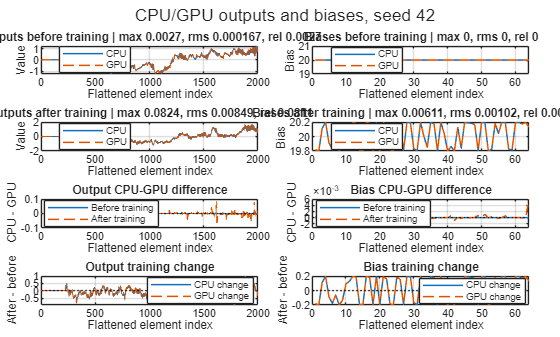

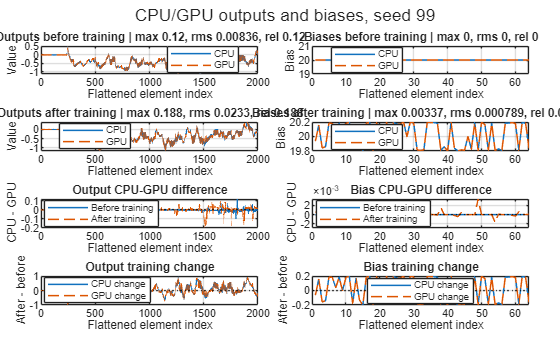

%% ---------------- Output and Bias Plots ----------------
% These figures show CPU and GPU outputs/biases before training, after training, and CPU-GPU differences.
snn_plot_check_outputs_and_biases(check_results);

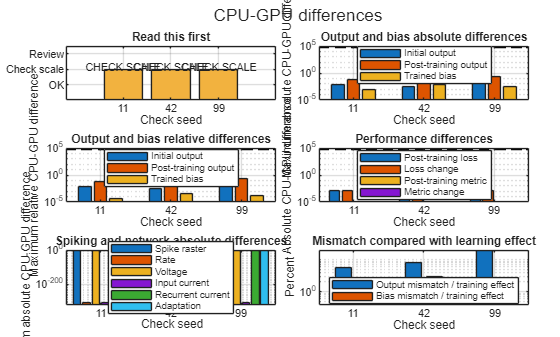

%% ---------------- Detailed Diagnostic Plots ----------------
% First read the verdict panel, then inspect any seed marked REVIEW or CHECK SCALE.
snn_plot_check_summary(summary);

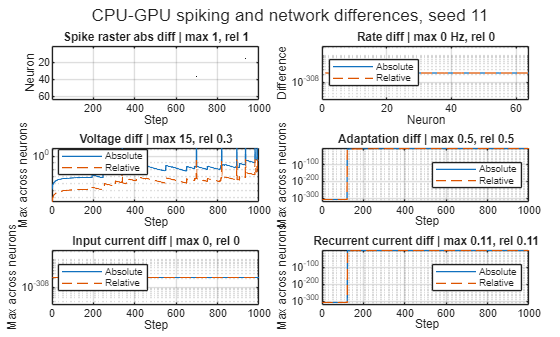

[CHECK neural] seed 11: Final CPU-trained and GPU-trained models are replayed with the CPU diagnostic recorder on the same trajectory.


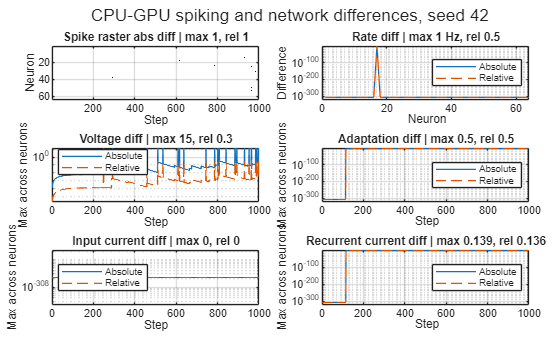

[CHECK neural] seed 42: Final CPU-trained and GPU-trained models are replayed with the CPU diagnostic recorder on the same trajectory.


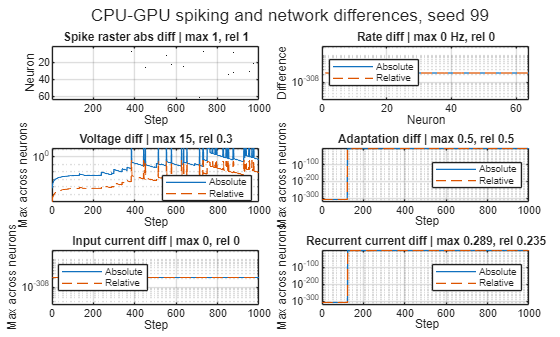

[CHECK neural] seed 99: Final CPU-trained and GPU-trained models are replayed with the CPU diagnostic recorder on the same trajectory.


snn_plot_check_neural_comparison(check_results);